# 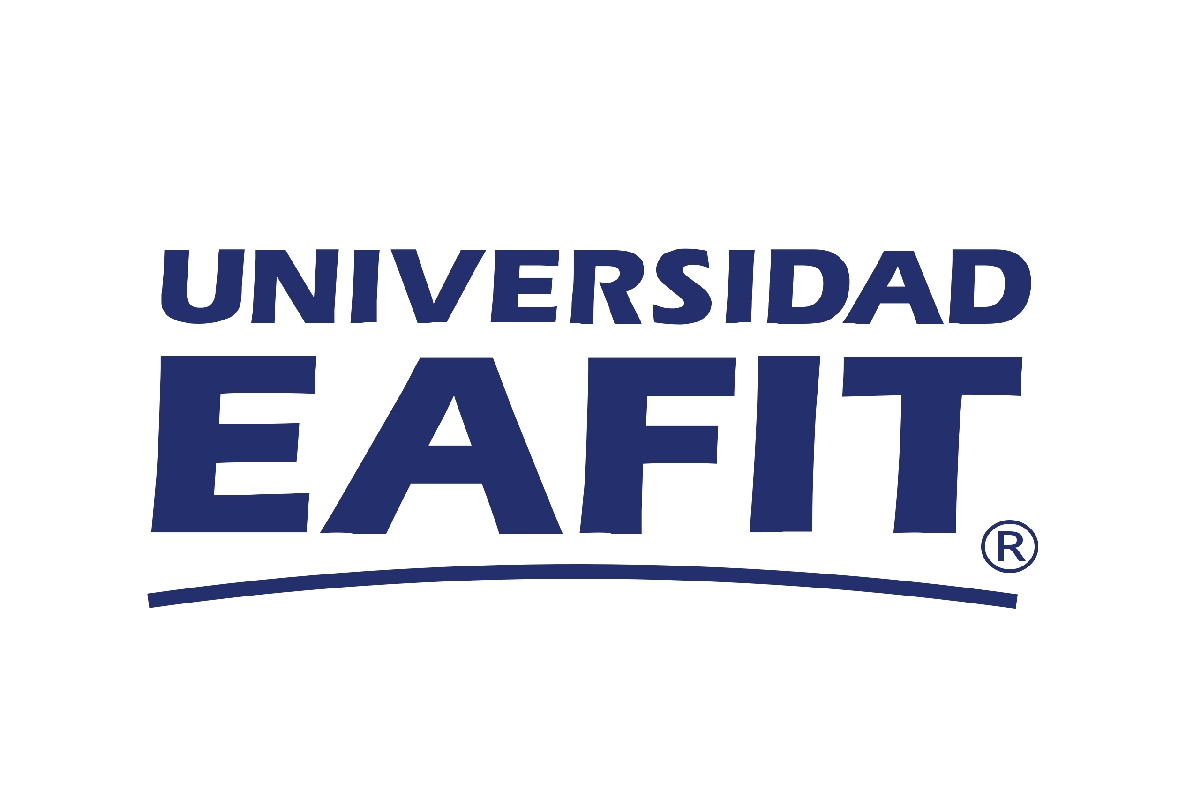                     Modelo del crecimiento de un tumor

Por Miguel Chacón y Felipe Henao, Universidad EAFIT.

## Introducción

En el desarrollo de este proyecto nos basamos en el trabajo de $\textit{De Pillis & Radunskaya (2003)}$. El modelo de este trabajo representa el crecimiento de un tumor y como es su respuesta a un tratamiento, hay diversos factores que intervienen en este proceso, principalmente la severidad de la enfermedad, la aplicación del tratamiento y la fuerza del sistema inmune del paciente.

En el modelo se incluyen células inmunitarias cuyo crecimiento puede verse afectado por la presencia del tumor, las células inmunitarias pueden destruir células tumorales por medio de un proceso cinético. También se incluyen unos términos de competencia, es decir, las células normales y las tumorales compiten por los recursos disponibles, mientras que las células inmunitarias y las tumorales compiten en una relación depredador-presa. En el modelo $ I(t)$ denota el número de células inmunitarias en el tiempo $t$, $T(t)$ el número de células tumorales o tumorales en el tiempo $t$, $N(t)$ el número de células normales, o huésped, en el tiempo t.

Se considera que la fuente de las células inmunitarias está fuera del sistema, por lo que es razonable suponer una tasa de afluencia constante s. Además, en ausencia de cualquier tumor, las células morirán a una tasa per cápita d1, lo que resulta en un tamaño de población a largo plazo de s/$d_1
$ células.

La presencia de células tumorales estimula la respuesta inmunitaria, representada por el término de crecimiento no lineal positivo de las células inmunitarias


$$\frac{\rho I(t)T(t)}{\alpha + T(t)}$$


$\rho$  y $\alpha$ son constantes positivas.

La reacción de las células inmunes y tumorales puede resultar en la muerte de las células tumorales o en la inactivación de las células inmunes, representadas por los dos términos de competición

$\frac{dI}{dt} = -c_1I(t)T(t) $ y $\frac{dT}{dt} = -c_2I(t)T(t)$

Tanto las células tumorales como las normales se modelan mediante una ley de crecimiento logística, con los parámetros $r_i$ y $b_i$ que representan las tasas de crecimiento $\textit{per cápita}$ y las capacidades de carga recíprocas de los dos tipos de células: $i = 1$ identifica los parámetros asociados al tumor, e $i = 2$ los asociados al tejido normal. Además, hay dos términos que representan la competencia entre las células tumorales y las del huésped. 

Al juntar todos los terminos mencionados anteriormente se obtiene el siguiente sistema de ecuaciones diferenciales ordinarias.


$$\dot{N} = r_2 N(1-b_2N)-c_4TN$$



$$\dot{T} = r_1T(1-b_1T)-c_2IT-c_3TN$$



$$\dot{I} = s + \frac{\rho IT}{\alpha + T} -c_1IT-d_1I$$


Se añade el efecto de la droga a este sistema. Se denota por $u(t)$ la cantidad de fármaco en la zona del tumor en el momento $t
$. Además,se supone que el fármaco mata todos los tipos de células, pero que la tasa de destrucción diferente para cada tipo de célula, con una curva de respuesta en todos los casos dada por una exponencial


$$F(u) = a(1-e^{-ku})$$


$F(u)$ es la muerte celular fraccionada para una cantidad dada de fármaco $U$, en el lugar del tumor. Dado que se desconocen los detalles de la farmacocinética, se establece $ k = 1$ como en estudios preliminares. Denotamos por $a_1$, $a_2$ y $a_3$ los tres coeficientes de respuesta diferentes. Se añaden estos términos al sistema de ecuaciones diferenciales anterior, así como una ecuación para $u(t)$, la cantidad de fármaco en el lugar del tumor. Ésta viene determinada por la dosis dada $v(t)$, y una tasa de decaimiento $\textit{per cápita}$ del fármaco una vez inyectado. Esta tasa de decaimiento incorpora todas las vías de eliminación del fármaco.

El sistema con interacción de fármacos viene dado por:


$$\dot{N} = r_2 N(1-b_2N)-c_4TN - a_3(1-e^{-u})N$$



$$\dot{T} = r_1T(1-b_1T)-c_2IT-c_3TN - a_2(1-e^{-u})T$$



$$\dot{I} = s + \frac{\rho IT}{\alpha + T} -c_1IT-d_1I- a_1(1-e^{-u})I$$



$$\dot{u}=v(t)-d_2u$$


#### Resumen del significado de terminos: 

- $N(t)$: El número de células normales, o huésped, en el tiempo $t$. Se usa $N(0) = 1$

- $T(t)$: El número de células tumorales o tumorales en el tiempo $t$. Se usa $T(0) = 0.25$

- $I(t)$: Denota el número de células inmunitarias en el tiempo $t
$. Se usa $I(0) = 0.15$ y $I(0) = 0.10$

- $a_i$ : Fraccion de muerte celular, $a_3 \leq a_1 \leq a_2$.  Se usa $a_1 = 0.2$, $a_2 = 0.3 $, y $a_3 = 0.1 $

- $b_1,b_2$: capacidades de barrido, $b_1^{-1}\leq b_2^{-1} = 1$. Se usa $b_1 = b_2 = 1.0$

- $c_1,c_2,c_3,c_4$ : Terminos de competicion. Se usa $c_1 = 1.0$, $c_2 = 0.5 $, $c_3 = 1.0 $ y $c_4 = 1.0 $

- $d_1,d_2$ : tasas de muerte, $d_1$ es la tasa de muerte $\textit{per capita}$ de celulas inmunes, y $d_2$ es la tasa de muerte $\textit{per capita}$ de la droga. Se usa $d_1 = 0.2$ y $d_2 = 1.0 $

- $r_1,r_2$ : tasa por unidad de crecimiento. En el trabajo asumimos que la poblacion de celular tumorales crece mas rápido que la población de celulas normales, es decir, $r_1>r_2$. Se usa $r_1 = 1.5$ y $r_2 = 1.0$

- $s$ : Tasa de fuente inmunitaria. $0<s\leq0.5$. Se usa $s = 0.33$

- $\alpha$ : Tasa de umbral inmune. Se usa $\alpha = 0.3$

- $\rho
$ : Tasa de respuesta inmune. Se usa $\rho=0.01$, para simular un paciente con un sistema inmunologico comprometido

#### Hipotesis:

Suministrar de forma prolongada y constante el regimen de medicamento será contraproducente para la salud del paciente ya que mata tanto las céluas cancérigenas como las inmunitarias.

Si la tasa de umbral inmune ($\alpha$) es alta, entonces se espera que el sistema inmunológico tenga una respuesta más efectiva contra las células tumorales.

Si la tasa de crecimiento de células tumorales es alta ($r_1$), mientras que la tasa de crecimiento de células normales es baja ($r_2$), entonces se espera que el tamaño del tumor aumente significativamente en comparación con el número de células normales.

## Métodos (Plan de solucion): 

- Con base en el documento de $\textit{De Pillis & Radunskaya (2003)}$ implementar el diagrama de bloques y mascaras del modelo en $\textit{Simulink}$.

- Basandonos en el trabajo de $\textit{De Pillis & Radunskaya (2003)}$ reallizar la verificacion de nuestro modelo, utilizando las graficas y puntos de equilibrio presentados en el documento.

- Realizar la simulacion del comportamiento del sistema con las entradas escalon, seno e impulso.

- Hacer simulaciones del comportamiento del sistema variando ciertos parametros del modelo ($a_1,\rho,\alpha,r_1$ y $r_2$).

- Analizar los resultados al realizar los experimentos anteriormente mencionados.

**Párametros**

clear all
clc

a1=0.2;
alpha=0.3;
r1=1.5;
r2=1;
rho=0.01;
t=0:0.1:150;
v=[t' zeros(size(t,2),1)];

## Resultados

**Figura del diagrama de bloques y máscaras**

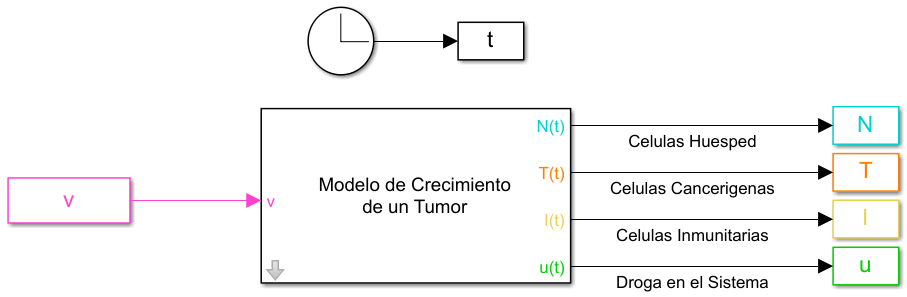

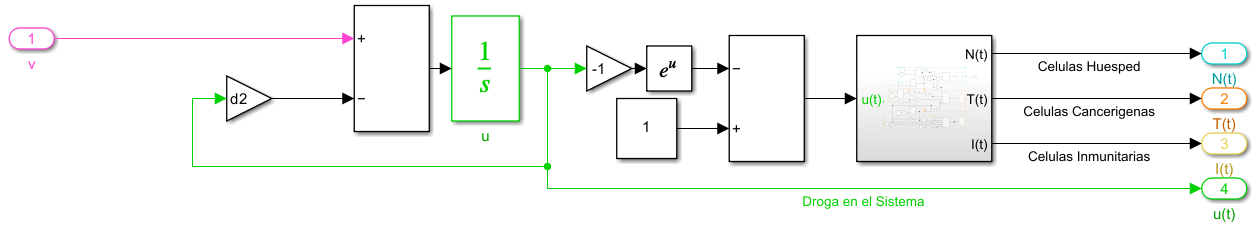

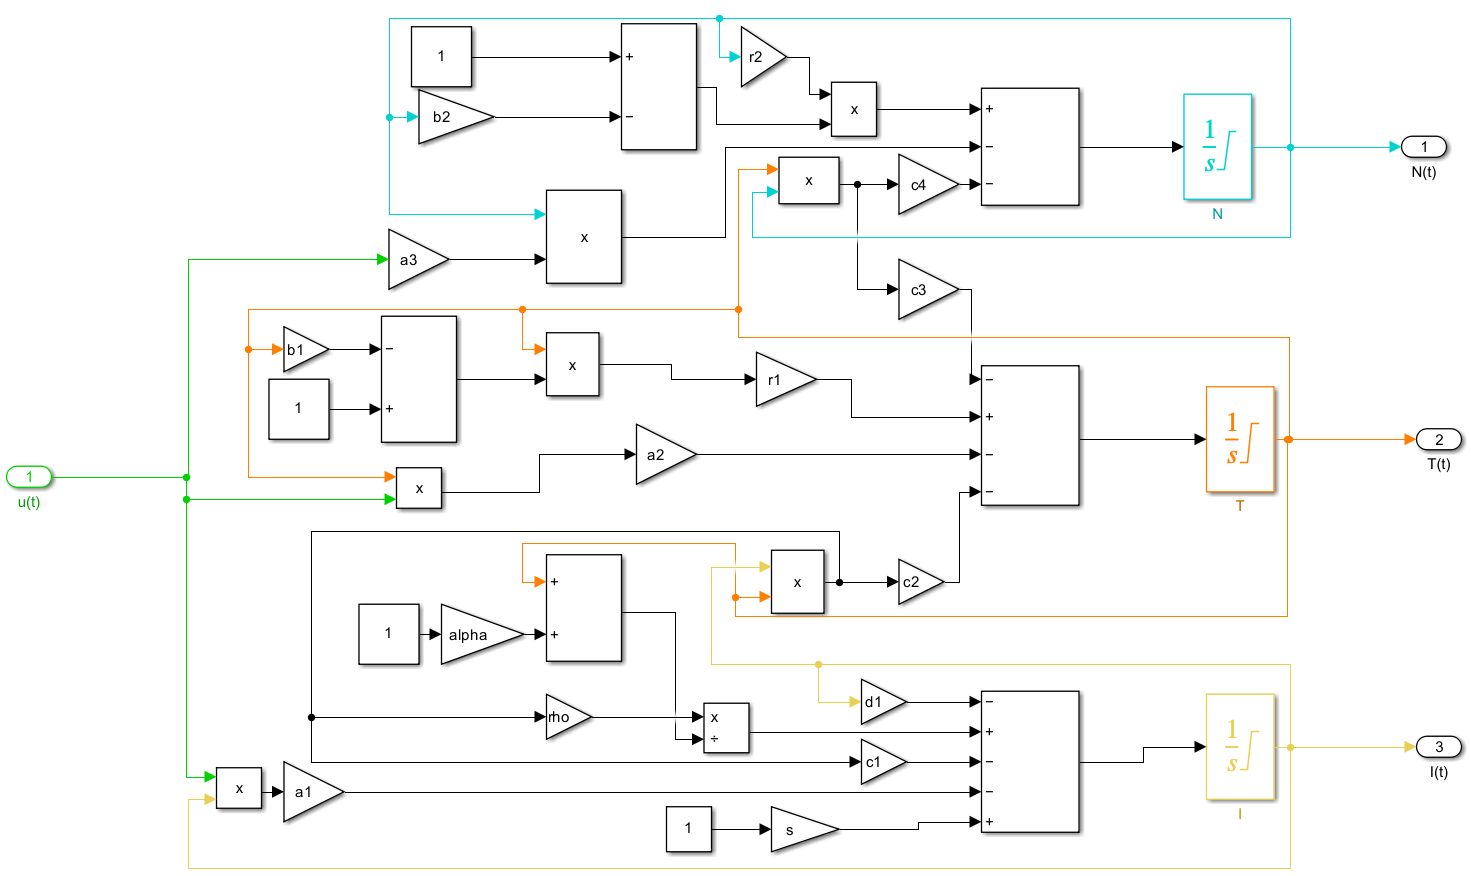

### **Verificación**

En primer lugar, se evaluara los puntos de equilibrio del sistema, y verficamos que sean los obtenidos teoricamente, los cuales fueron encontrados en el trabajo de $\textit{De Pillis & Radunskaya (2003)}$.

**Equilibrio de Coexistencia Estable**

Uno de los equilibrios del sitema es un equilibrio de coexistencia estable, ese equilibrio ocurre cuando ambas las celulas normales y tumorales coexisten con poblaciones distintas de cero, para la configuracion de parámetros que se tiene este equilibrio se encuentra en N=0.44, T=0.56 y I=0.44 .

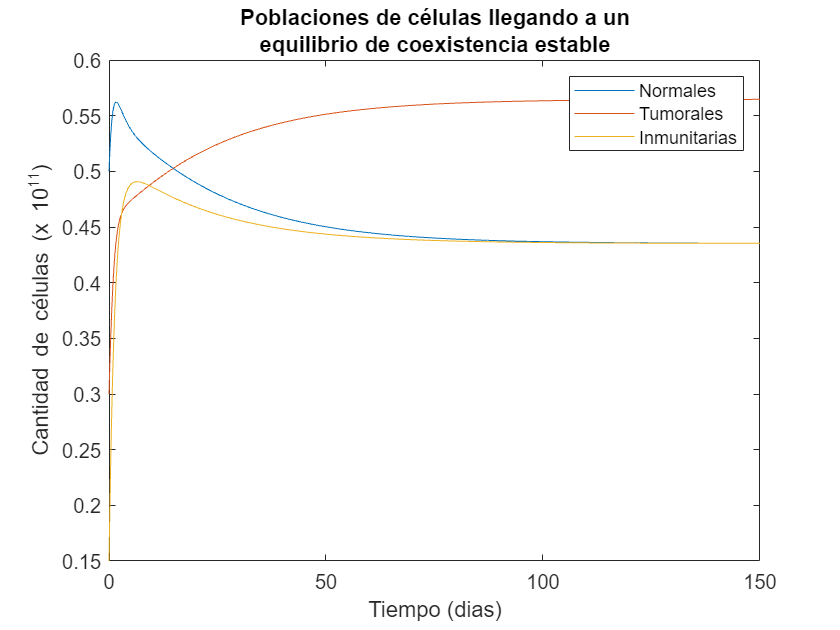

ci=[0.5 0.3 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células llegando a un", ...
    "equilibrio de coexistencia estable"])

**Equilibrio Libre de Tumor**

Otro equilibrio del sitema es un equilibrio libre de tumor, que, como su nombre lo dice, en este equilibro la poblacion de las células cangerigenas es cero y las células normales sobreviven, para la configuracion de parámetros que se tiene este equilibrio se encuentra en N=1, T=0 y I=1.65.

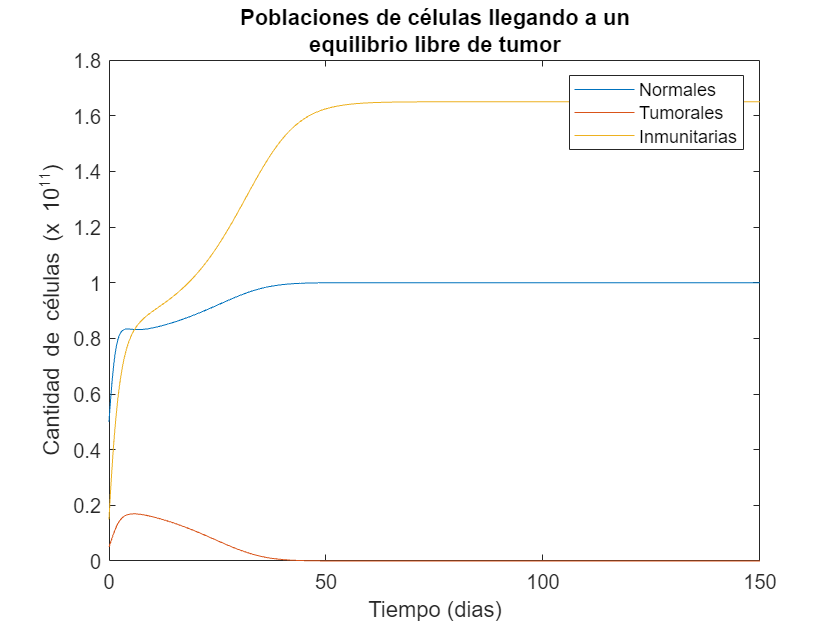

%Equilibrio libre de tumor
%(1,0,1.65)
ci=[0.5 0.05 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células llegando a un","equilibrio libre de tumor"])

**Equilibrio Muerto**

El ultimo equilibrio del sitema es el equilibrio muerto, en el cual la población de células normales es cero. Este equilibrio se puede dar de dos formas, el tipo 1 es cuando la población de células cangerigenas también muere, y el tipo 2 es cuando estas sobreviven. Para la configuracion de parámetros que se tiene el equilibrio tipo 1 se encuentra en N=0, T=0 y I=1.65 y el tipo 2 en N=0, T=0.89924 y I=0.302268.

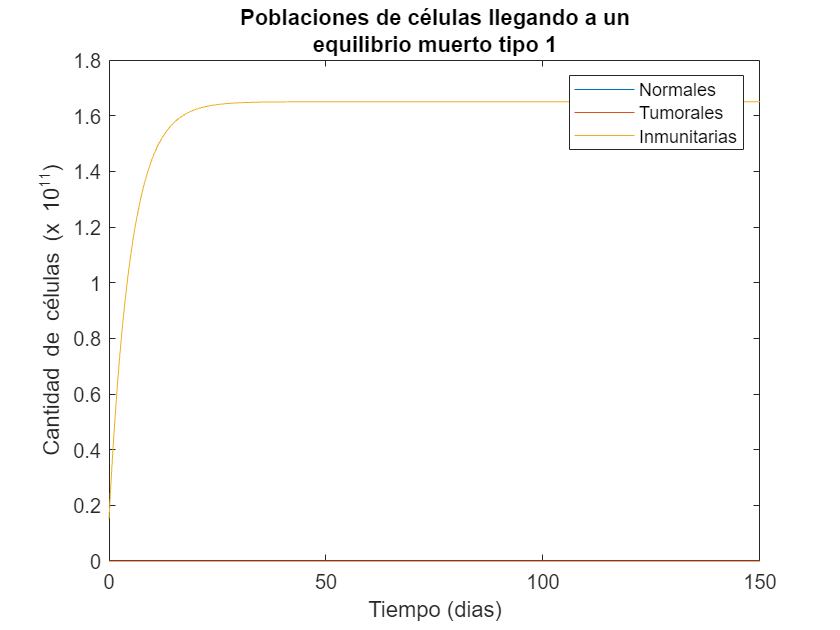


%Equilibrio muerto tipo 1
ci=[0 0 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células llegando a un","equilibrio muerto tipo 1"])

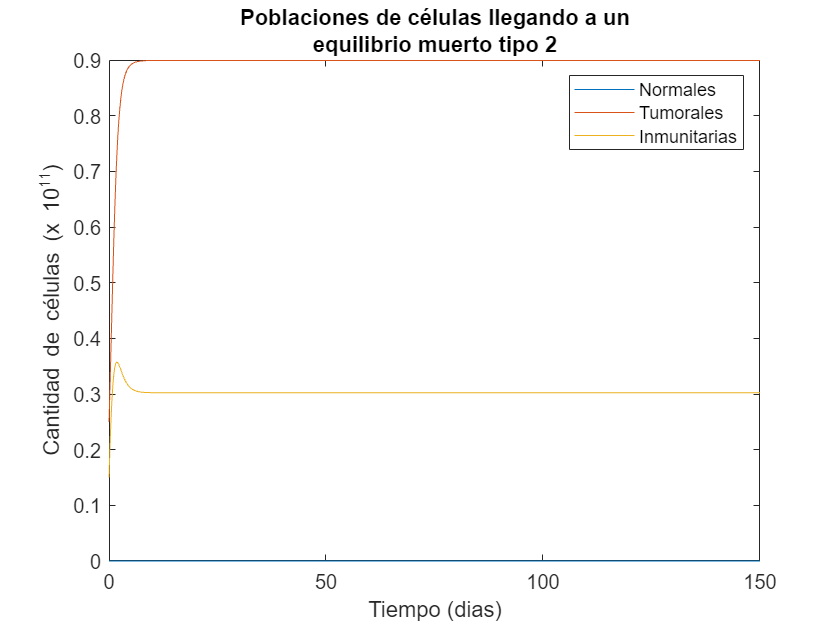

%Equilibrio muerto tipo 2
ci=[0 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células llegando a un","equilibrio muerto tipo 2"])

En las graficas anteriores, se puede ver que el sistema logra alcanzar todos los equilibrios descritos, esto es, las poblaciones al llegar a esos puntos se quedan constantes. Esto nos ayuda a corroborar el buen funcionamiento de la implementación del sistema.

#### **Comparación con Graficas Obtenidas**

Ahora, comparamos las graficas que se obtuvieron de resultados en el trabajo de $\textit{De Pillis & Radunskaya (2003)}$ con aquellas obtenidas con nuestro modelo.

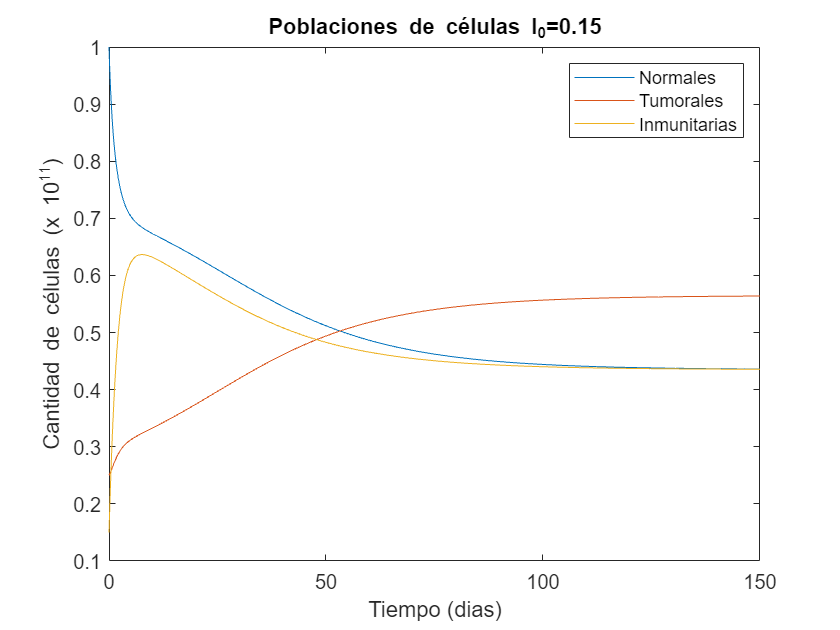

%Comparación graficas paper

ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title("Poblaciones de células I_{0}=0.15")

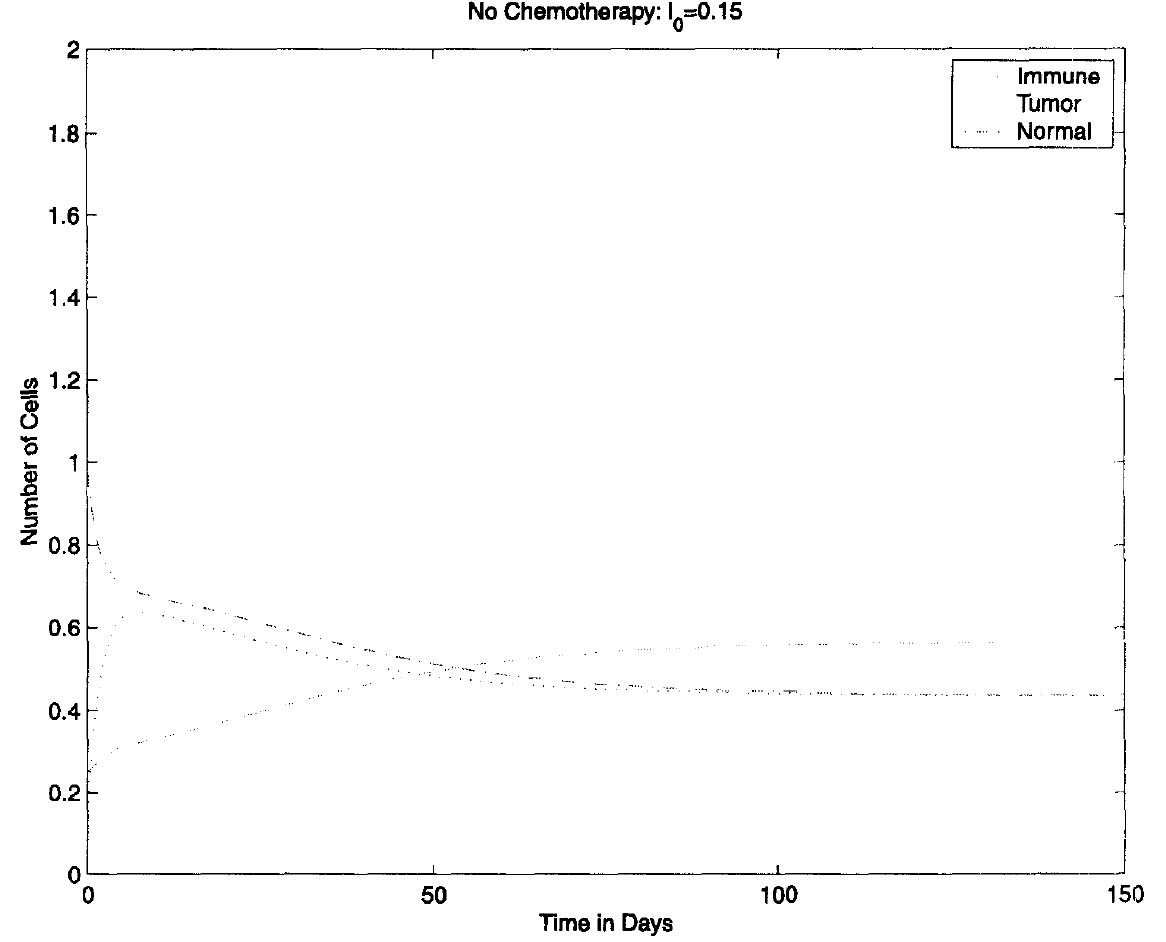

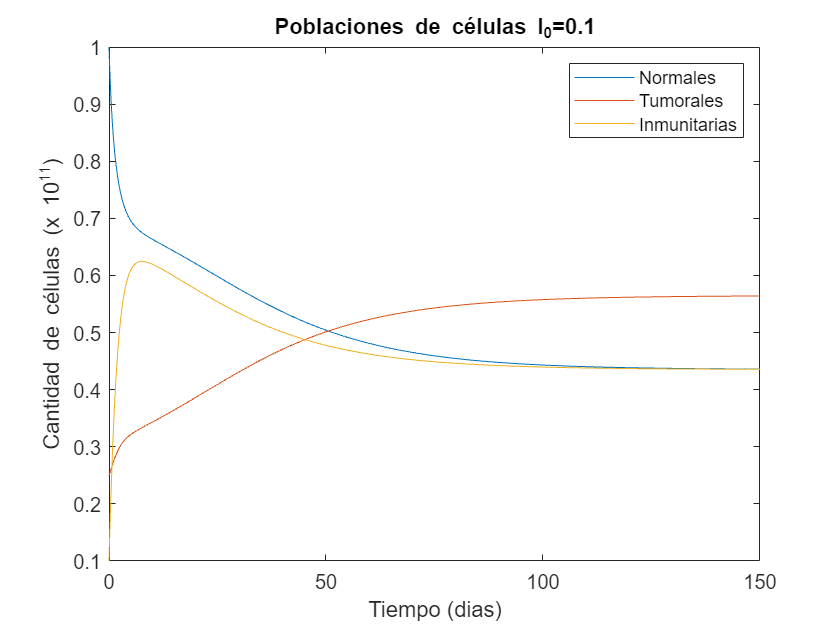

ci=[1 0.25 0.1 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title("Poblaciones de células I_{0}=0.1")

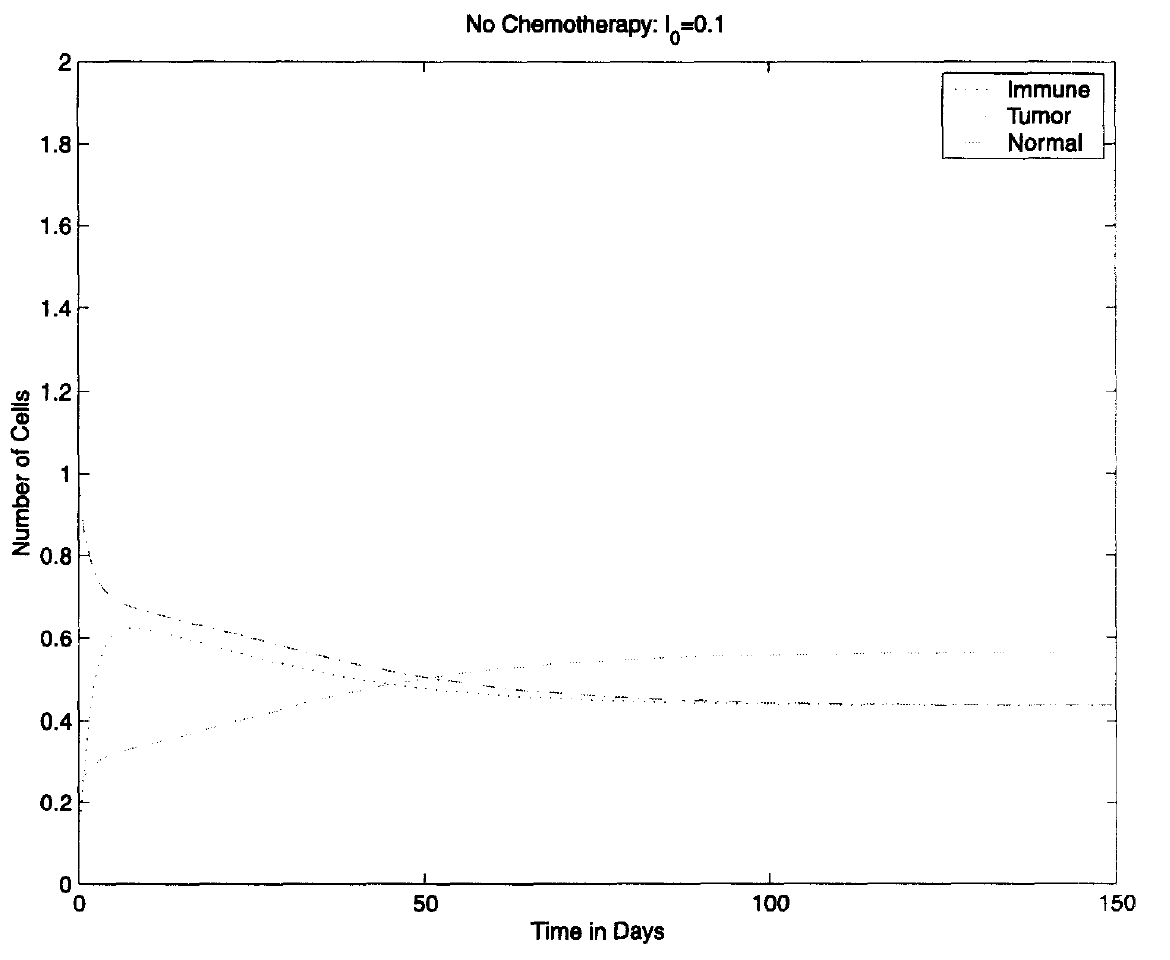

## **Simulación con distintas entradas**

#### **Entrada Escalón**

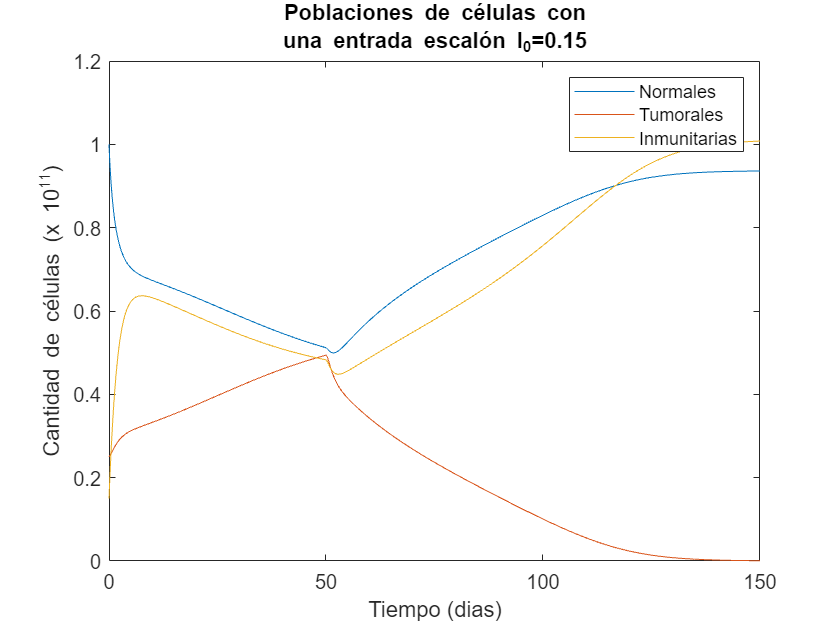

% Escalón
delay=50;
v=[t heaviside(t-delay)];
ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células con", "una entrada escalón I_{0}=0.15"])

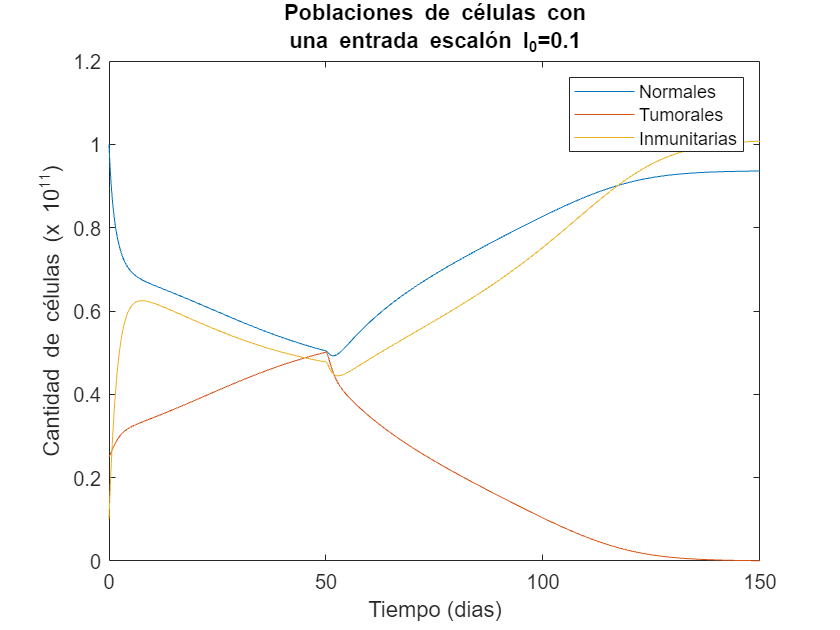


ci=[1 0.25 0.1 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células con", "una entrada escalón I_{0}=0.1"])

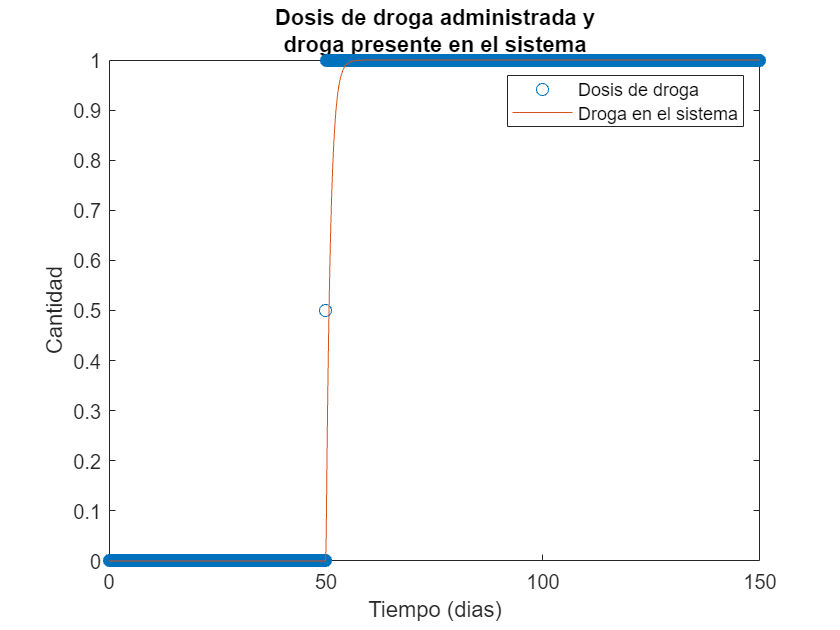

plot(t,v(:,2) ,'o')
hold on
plot(t,u)
hold off
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Dosis de droga" "Droga en el sistema"])
title(["Dosis de droga administrada y", "droga presente en el sistema"])

#### **Entrada Pulso**

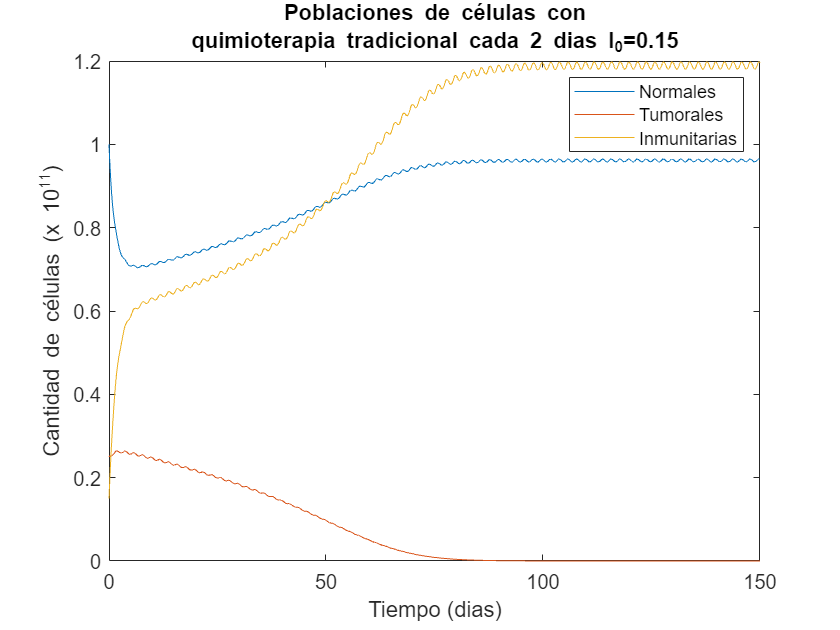

%Pulso
periodo=2;
d=0:periodo:150;
y=pulstran(t,d,@rectpuls);
v=[t y];

ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células con", ...
    "quimioterapia tradicional cada 2 dias I_{0}=0.15"])

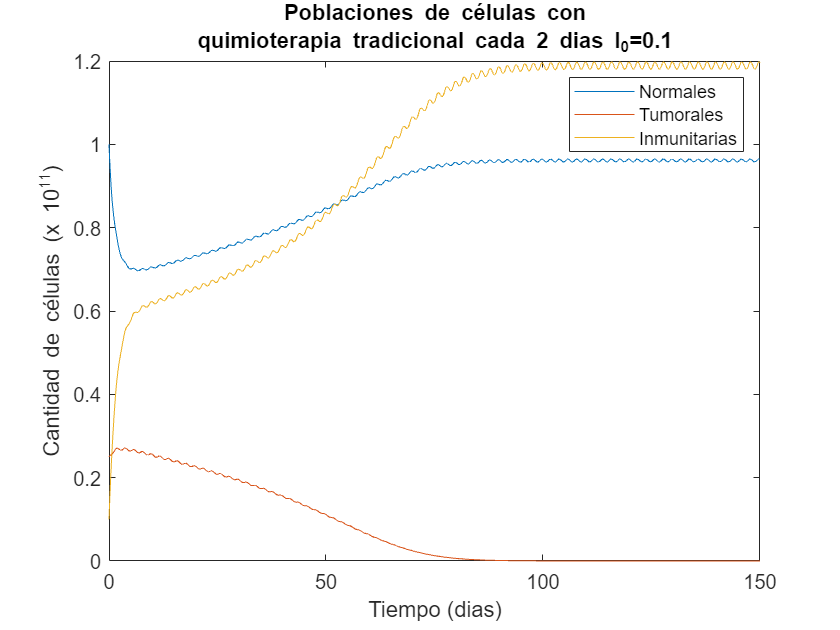

ci=[1 0.25 0.1 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células con", ...
    "quimioterapia tradicional cada 2 dias I_{0}=0.1"])

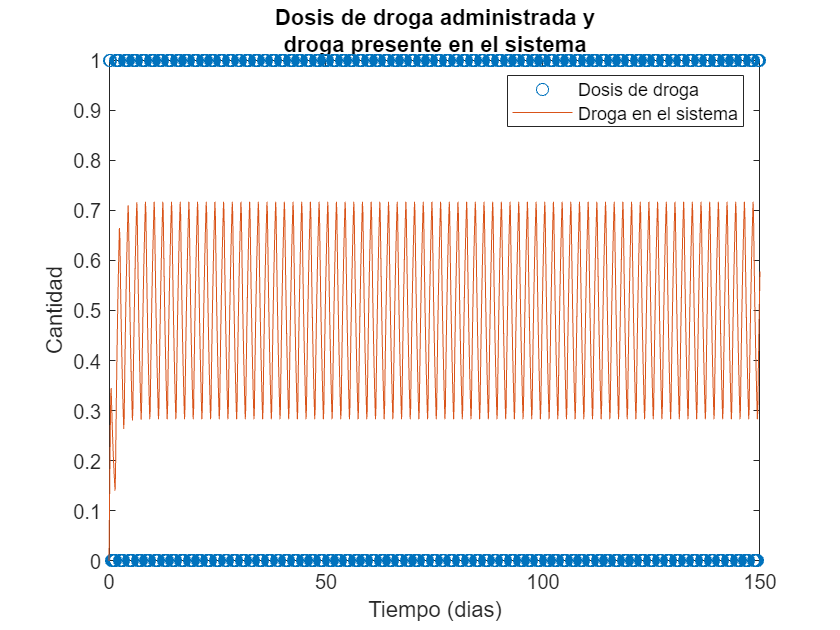

plot(t,v(:,2) ,'o')
hold on
plot(t,u)
hold off
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Dosis de droga" "Droga en el sistema"])
title(["Dosis de droga administrada y", "droga presente en el sistema"])

#### **Entrada Seno**

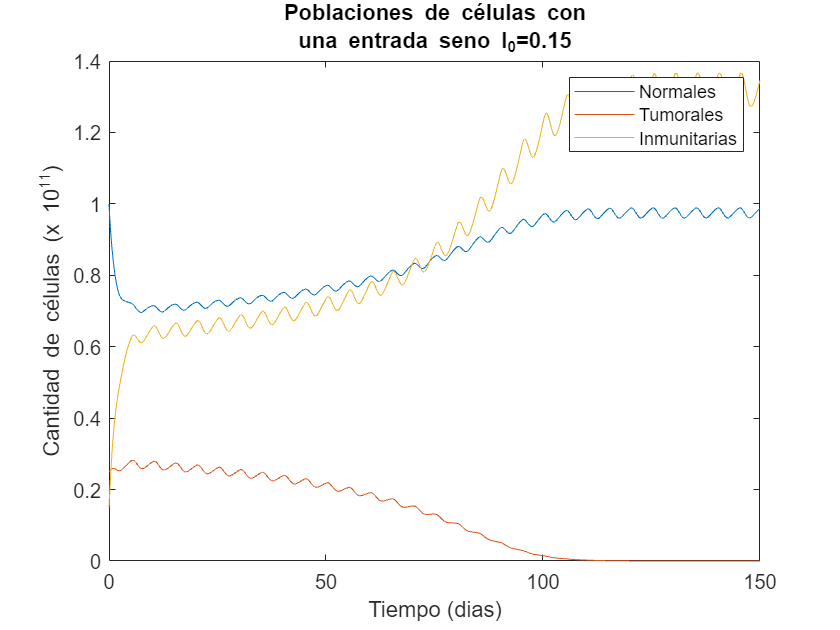

% Seno
A=1;   %amplitud
f=0.2; %frecuencia
v=[t max(A*sin(2*pi*f*t),0)];

ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células con", "una entrada seno I_{0}=0.15"])

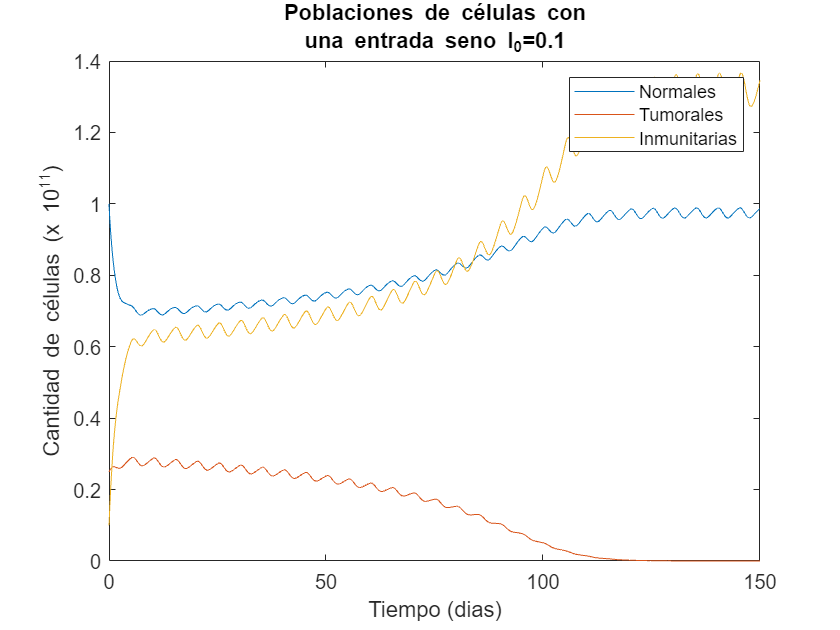


ci=[1 0.25 0.1 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);
sim("ModeloPractica")
plot(t,[N T I])
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(["Normales" "Tumorales" "Inmunitarias"])
title(["Poblaciones de células con", "una entrada seno I_{0}=0.1"])

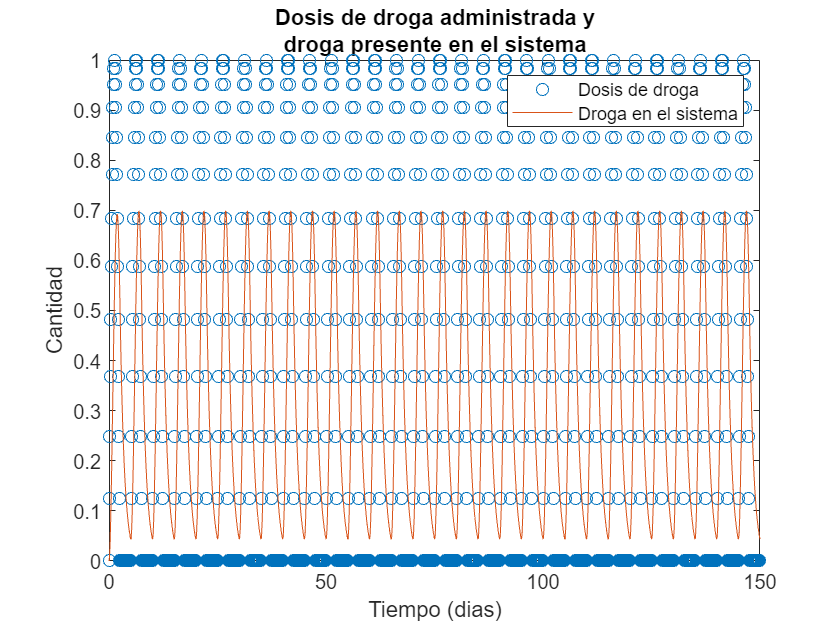

plot(t,v(:,2) ,'o')
hold on
plot(t,u)
hold off
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Dosis de droga" "Droga en el sistema"])
title(["Dosis de droga administrada y", "droga presente en el sistema"])

## **Simulación con variación en los parámetros **

Ahora, se hará una simulacion al variar la fraccion de muerte de celulas inmunitarias por el tratamiento y la tasa de respuesta inmune del paciente, cada uno por separado, teniendo como entrada un pulso cada 2 dias.

%Entrada y condiciones iniciales
periodo=2;
d=0:periodo:150;
y=pulstran(t,d,@rectpuls);
v=[t y];
ci=[1 0.25 0.15 0];
N0=ci(1);
T0=ci(2);
I0=ci(3);
u0=ci(4);

#### Fracción de muerte de celulas inmunitarias por el tratamiento ($a_1
$)

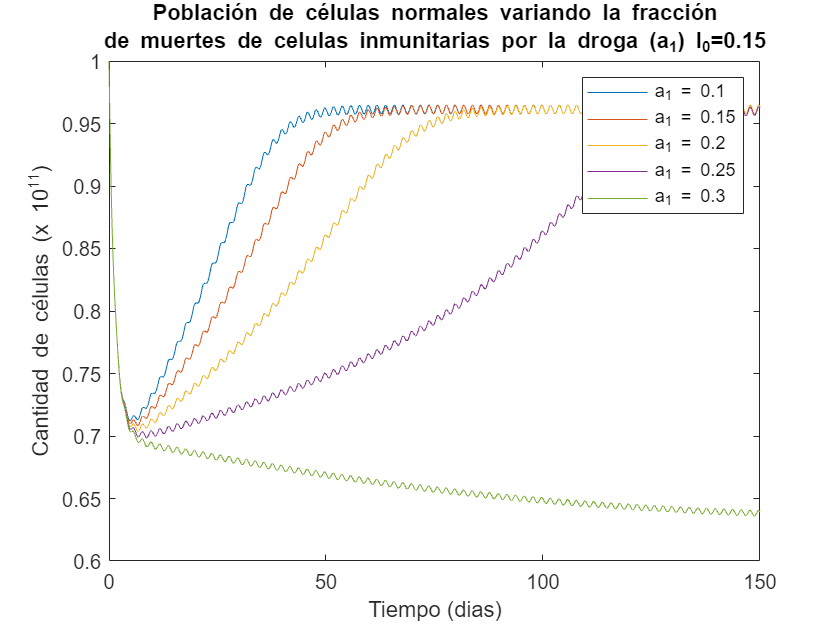

alpha=0.3;
r1=1.5;
r2=1;
rho=0.01;
% a1 - fraccion de muerte de celulas inmunitarias por el tratamiento
val=0.1:0.05:0.3;
n=length(val);
Nt=length(t);
Ni=zeros(Nt,n);
Ti=zeros(Nt,n);
Ii=zeros(Nt,n);

NTab=zeros(n,3);
TTab=zeros(n,3);
ITab=zeros(n,3);
NTab(:,1)=val;
TTab(:,1)=val;
ITab(:,1)=val;

for i=1:n
    a1=val(i);
    sim("ModeloPractica")
    Ni(:,i)=N;
    Ti(:,i)=T;
    Ii(:,i)=I;
end

leg="a_{1} = "+string(val);

plot(t,Ni)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células normales variando la fracción", ...
    "de muertes de celulas inmunitarias por la droga (a_{1}) I_{0}=0.15"])

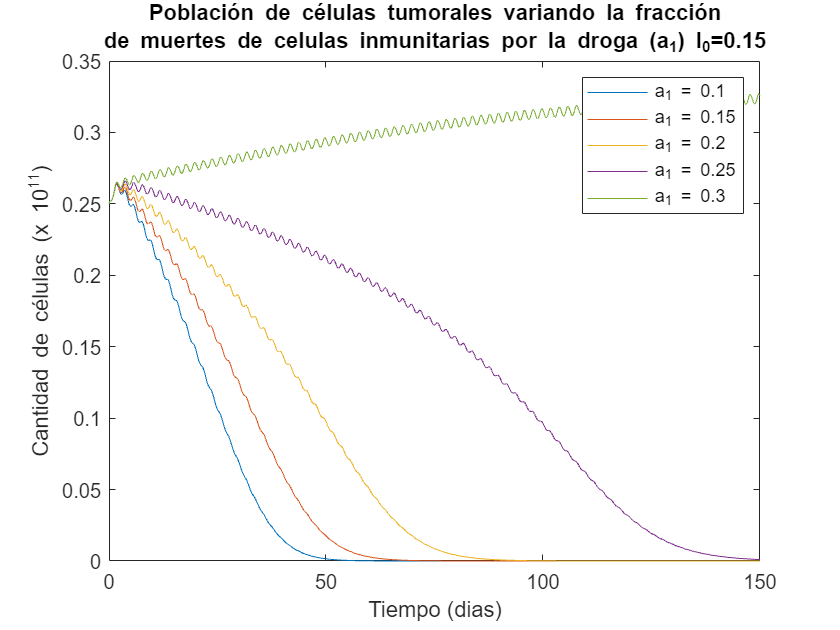

plot(t,Ti)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células tumorales variando la fracción", ...
    "de muertes de celulas inmunitarias por la droga (a_{1}) I_{0}=0.15"])

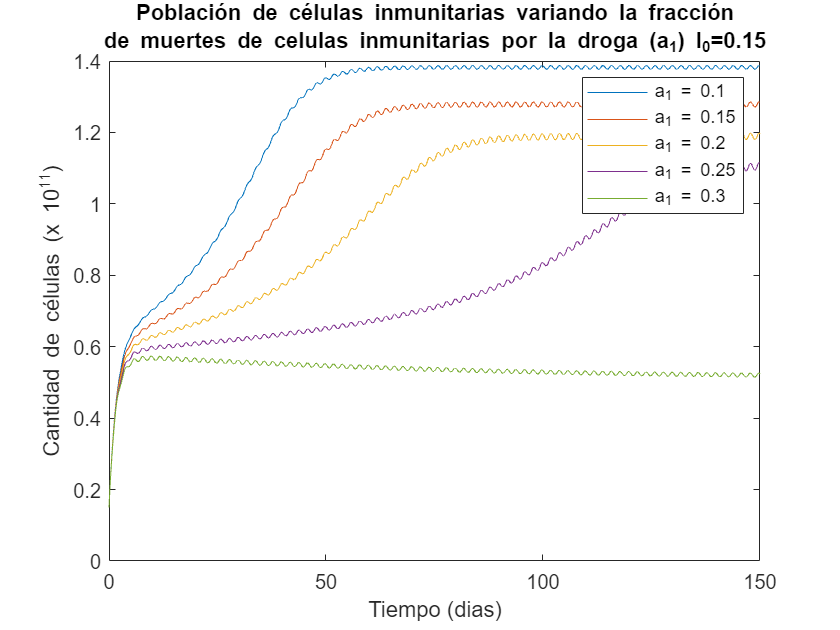

plot(t,Ii)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células inmunitarias variando la fracción", ...
    "de muertes de celulas inmunitarias por la droga (a_{1}) I_{0}=0.15"])

NTab(:,3)=round(min(Ni)',2);
NTab(:,2)=[0.96 0.96 0.96 0.96 NaN]';

TTab(:,3)=round(max(Ti)',2);
TTab(:,2)=[0 0 0 0 0.32]';

ITab(:,3)=round(max(Ii)',2);
ITab(:,2)=[1.38 1.28 1.19 1.02 0.52]';

plot(t,v(:,2) ,'o')
hold on
plot(t,u)
hold off
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Dosis de droga" "Droga en el sistema"])
title(["Dosis de droga administrada y", "droga presente en el sistema"])

VarNames=["a1" "Valor Estable" "Valor Mínimo"];
NTab=array2table(NTab,'VariableNames',VarNames);
NTab = table(NTab,'VariableNames',"Células Normales");
VarNames(end)="Valor Máximo";
TTab=array2table(TTab,'VariableNames',VarNames);
TTab = table(TTab,'VariableNames',"Células Cancerigenas");
ITab=array2table(ITab,'VariableNames',VarNames);
ITab = table(ITab,'VariableNames',"Células Inmunitarias");
disp(NTab)

              Células Normales           
     a1     Valor Estable    Valor Mínimo
    _____________________________________

     0.1        0.96             0.71    
    0.15        0.96             0.71    
     0.2        0.96              0.7    
    0.25        0.96              0.7    
     0.3         NaN             0.64    



disp(TTab)

            Células Cancerigenas         
     a1     Valor Estable    Valor Máximo
    _____________________________________

     0.1           0             0.26    
    0.15           0             0.26    
     0.2           0             0.26    
    0.25           0             0.27    
     0.3        0.32             0.33    



disp(ITab)

            Células Inmunitarias         
     a1     Valor Estable    Valor Máximo
    _____________________________________

     0.1        1.38             1.39    
    0.15        1.28             1.29    
     0.2        1.19              1.2    
    0.25        1.02             1.12    
     0.3        0.52             0.57    



#### Tasa de respuesta inmune ($\rho$)

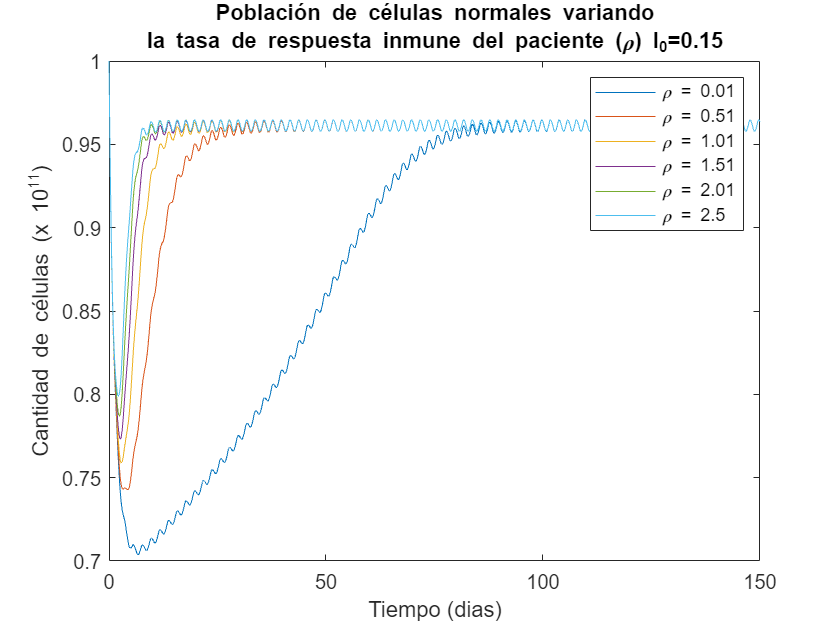

a1=0.2;
alpha=0.3;
r1=1.5;
r2=1;
%rho - tasa de respuesta inmune

val=[0.01:0.5:2.5 2.5];
n=length(val);
Nt=length(t);
Ni=zeros(Nt,n);
Ti=zeros(Nt,n);
Ii=zeros(Nt,n);

NTab=zeros(n,3);
TTab=zeros(n,3);
ITab=zeros(n,3);
NTab(:,1)=val;
TTab(:,1)=val;
ITab(:,1)=val;


for i=1:n
    rho=val(i);
    sim("ModeloPractica")
    Ni(:,i)=N;
    Ti(:,i)=T;
    Ii(:,i)=I;
end

leg="\rho = "+string(val);

plot(t,Ni)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células normales variando", ...
    "la tasa de respuesta inmune del paciente (\rho) I_{0}=0.15"])

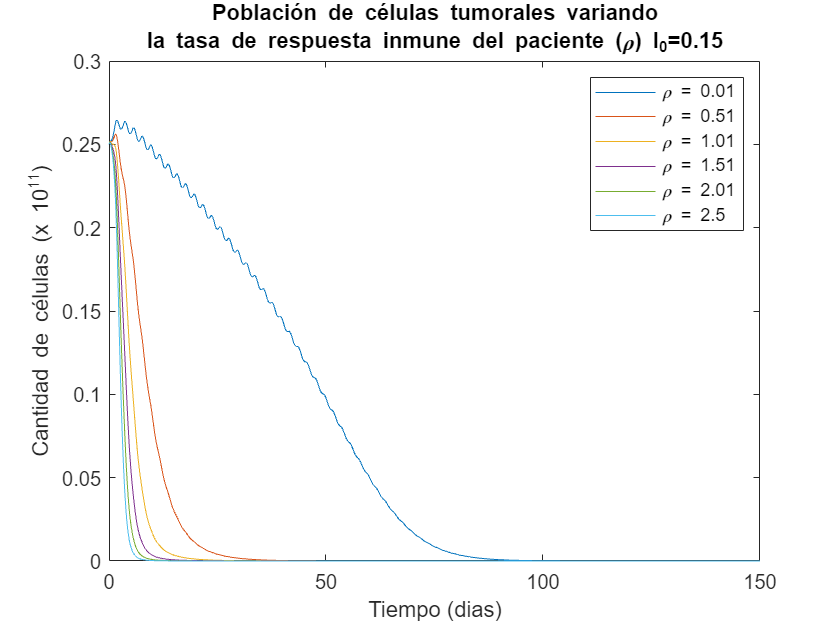

plot(t,Ti)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células tumorales variando", ...
    "la tasa de respuesta inmune del paciente (\rho) I_{0}=0.15"])

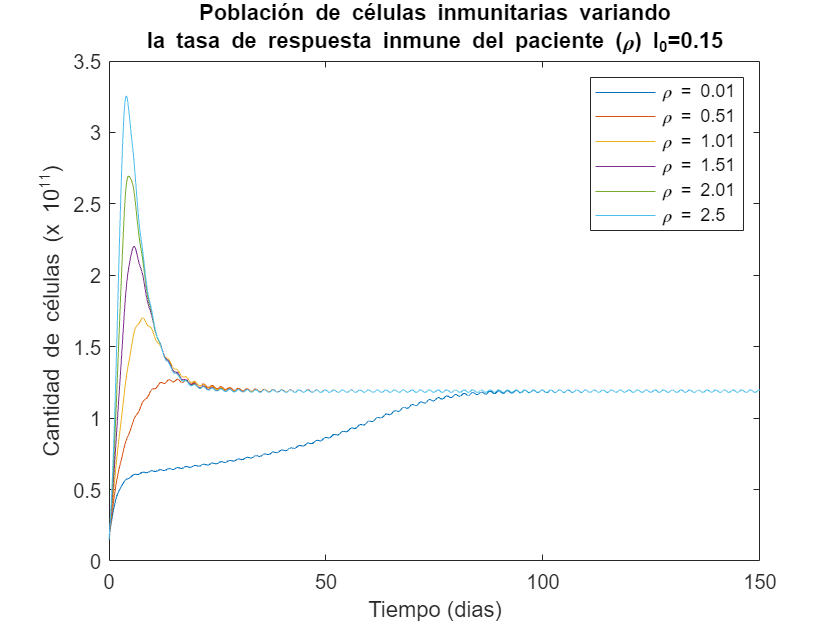

plot(t,Ii)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células inmunitarias variando", ...
    "la tasa de respuesta inmune del paciente (\rho) I_{0}=0.15"])


NTab(:,3)=round(min(Ni)',2);
NTab(:,2)=[0.96 0.96 0.96 0.96 0.96 0.96]';

TTab(:,3)=round(max(Ti)',2);
TTab(:,2)=[0 0 0 0 0 0]';

ITab(:,3)=round(max(Ii)',2);
ITab(:,2)=[1.19 1.19 1.19 1.19 1.19 1.19]';

plot(t,v(:,2) ,'o')
hold on
plot(t,u)
hold off
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Dosis de droga" "Droga en el sistema"])
title(["Dosis de droga administrada y", "droga presente en el sistema"])


VarNames=["rho" "Valor Estable" "Valor Mínimo"];
NTab=array2table(NTab,'VariableNames',VarNames);
NTab = table(NTab,'VariableNames',"Células Normales");
VarNames(end)="Valor Máximo";
TTab=array2table(TTab,'VariableNames',VarNames);
TTab = table(TTab,'VariableNames',"Células Cancerigenas");
ITab=array2table(ITab,'VariableNames',VarNames);
ITab = table(ITab,'VariableNames',"Células Inmunitarias");
disp(NTab)

              Células Normales           
    rho     Valor Estable    Valor Mínimo
    _____________________________________

    0.01        0.96              0.7    
    0.51        0.96             0.74    
    1.01        0.96             0.76    
    1.51        0.96             0.77    
    2.01        0.96             0.79    
     2.5        0.96              0.8    



disp(TTab)

            Células Cancerigenas         
    rho     Valor Estable    Valor Máximo
    _____________________________________

    0.01          0              0.26    
    0.51          0              0.26    
    1.01          0              0.25    
    1.51          0              0.25    
    2.01          0              0.25    
     2.5          0              0.25    



disp(ITab)

            Células Inmunitarias         
    rho     Valor Estable    Valor Máximo
    _____________________________________

    0.01        1.19              1.2    
    0.51        1.19             1.27    
    1.01        1.19              1.7    
    1.51        1.19              2.2    
    2.01        1.19             2.69    
     2.5        1.19             3.26    



#### Tasa de umbral inmune ($\alpha$)

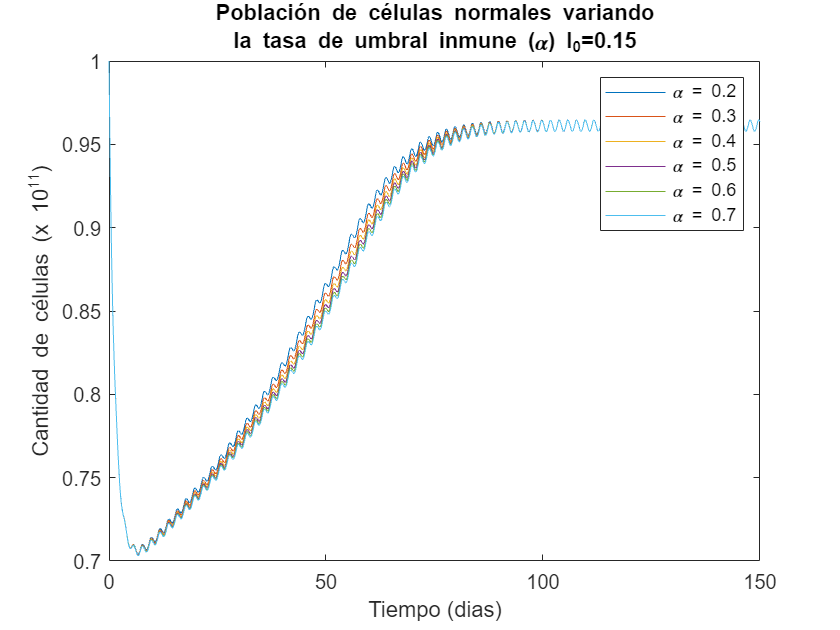

a1=0.2;
r1=1.5;
r2=1;
rho=0.01;
%alpha - tasa de umbral inmune

val=0.2:0.1:0.7;
n=length(val);
Nt=length(t);
Ni=zeros(Nt,n);
Ti=zeros(Nt,n);
Ii=zeros(Nt,n);

NTab=zeros(n,3);
TTab=zeros(n,3);
ITab=zeros(n,3);
NTab(:,1)=val;
TTab(:,1)=val;
ITab(:,1)=val;


for i=1:n
    alpha=val(i);
    sim("ModeloPractica")
    Ni(:,i)=N;
    Ti(:,i)=T;
    Ii(:,i)=I;
end

leg="\alpha = "+string(val);

plot(t,Ni)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células normales variando", ...
    "la tasa de umbral inmune (\alpha) I_{0}=0.15"])

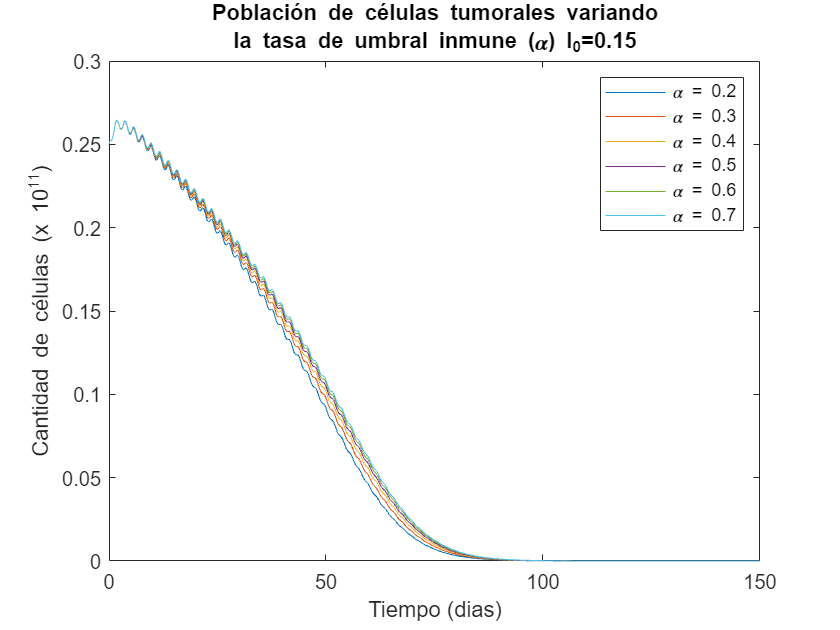

plot(t,Ti)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células tumorales variando", ...
    "la tasa de umbral inmune (\alpha) I_{0}=0.15"])

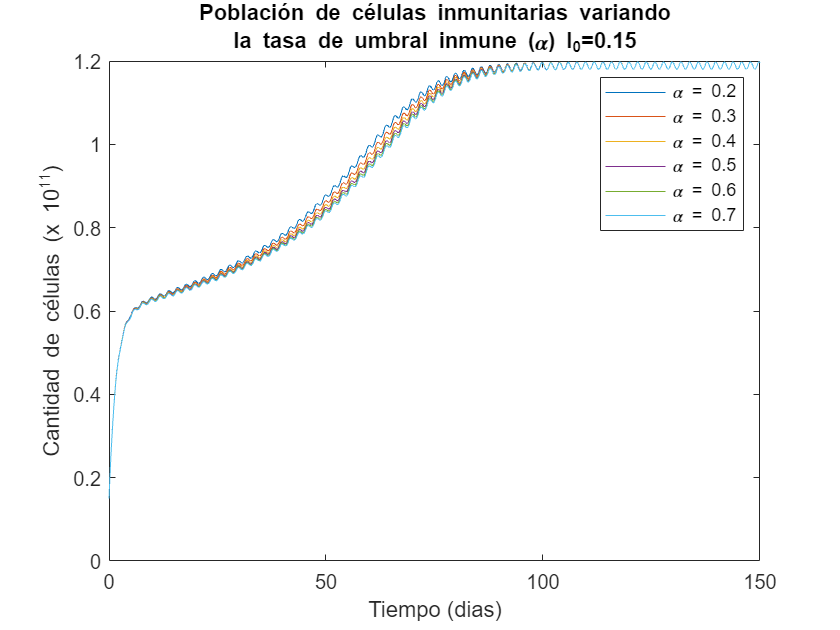

plot(t,Ii)
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células inmunitarias variando", ...
    "la tasa de umbral inmune (\alpha) I_{0}=0.15"])


NTab(:,3)=round(min(Ni)',2);
NTab(:,2)=[0.96 0.96 0.96 0.96 0.96 0.96]';

TTab(:,3)=round(max(Ti)',2);
TTab(:,2)=[0 0 0 0 0 0]';

ITab(:,3)=round(max(Ii)',2);
ITab(:,2)=[1.19 1.19 1.19 1.19 1.19 1.19]';

plot(t,v(:,2) ,'o')
hold on
plot(t,u)
hold off
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Dosis de droga" "Droga en el sistema"])
title(["Dosis de droga administrada y", "droga presente en el sistema"])


VarNames=["alpha" "Valor Estable" "Valor Mínimo"];
NTab=array2table(NTab,'VariableNames',VarNames);
NTab = table(NTab,'VariableNames',"Células Normales");
VarNames(end)="Valor Máximo";
TTab=array2table(TTab,'VariableNames',VarNames);
TTab = table(TTab,'VariableNames',"Células Cancerigenas");
ITab=array2table(ITab,'VariableNames',VarNames);
ITab = table(ITab,'VariableNames',"Células Inmunitarias");
disp(NTab)

               Células Normales           
    alpha    Valor Estable    Valor Mínimo
    ______________________________________

     0.2         0.96             0.7     
     0.3         0.96             0.7     
     0.4         0.96             0.7     
     0.5         0.96             0.7     
     0.6         0.96             0.7     
     0.7         0.96             0.7     



disp(TTab)

             Células Cancerigenas         
    alpha    Valor Estable    Valor Máximo
    ______________________________________

     0.2           0              0.26    
     0.3           0              0.26    
     0.4           0              0.26    
     0.5           0              0.26    
     0.6           0              0.26    
     0.7           0              0.26    



disp(ITab)

             Células Inmunitarias         
    alpha    Valor Estable    Valor Máximo
    ______________________________________

     0.2         1.19             1.2     
     0.3         1.19             1.2     
     0.4         1.19             1.2     
     0.5         1.19             1.2     
     0.6         1.19             1.2     
     0.7         1.19             1.2     



#### Tasas de crecimiento ($r_1$ y $r_2$)

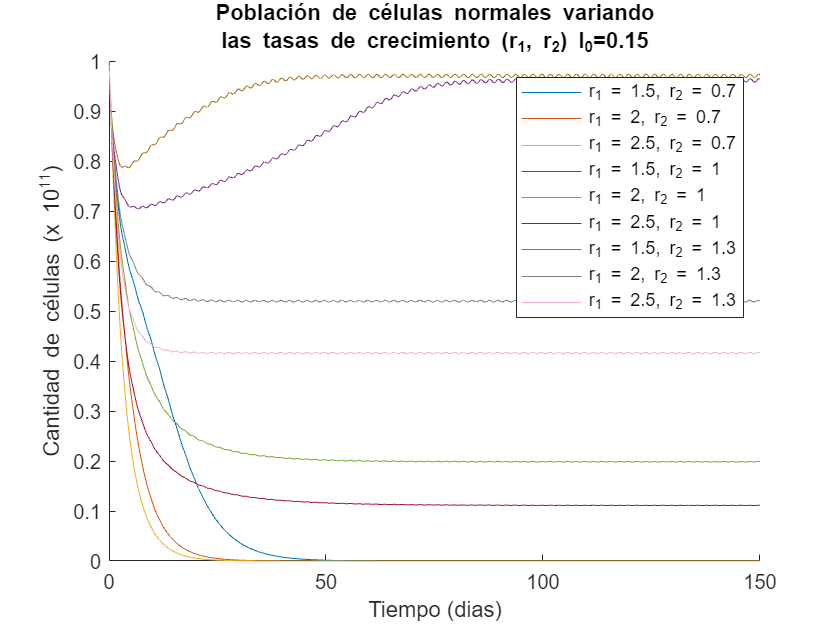

a1=0.2;
alpha=0.3;
rho=0.01;
%r1,r2 - tasas de crecimiento

val2=0.7:0.3:1.3;
n=length(val2);
val1=1.5:0.5:2.5;
n2=length(val1);
val=zeros(n*n2,2);
for j=1:n
    i=j-1;
    val(i*n+1:i*n+n2,2)=val2(j);
    val(i*n+1:i*n+n2,1)=val1';
end

n=size(val,1);
Nt=length(t);
Ni=zeros(Nt,n);
Ti=zeros(Nt,n);
Ii=zeros(Nt,n);

NTab=zeros(n,4);
TTab=zeros(n,3);
ITab=zeros(n,3);
NTab(:,1:2)=val;
TTab(:,1:2)=val;
ITab(:,1:2)=val;


for i=1:n
    r1=val(i,1);
    r2=val(i,2);
    sim("ModeloPractica")
    Ni(:,i)=N;
    Ti(:,i)=T;
    Ii(:,i)=I;
end

leg="r_{1} = "+string(val(:,1)) + ", r_{2} = "+string(val(:,2));

colors = [0, 0.4470, 0.7410;   % Blue
    0.8500, 0.3250, 0.0980;   % Orange    
    0.9290, 0.6940, 0.1250;   % Yellow    
    0.4940, 0.1840, 0.5560;   % Purple    
    0.4660, 0.6740, 0.1880;   % Green    
    0.6350, 0.0780, 0.1840;   % Red    
    0.6350, 0.4470, 0.1250;   % Brown    
    0.5, 0.5, 0.5;   % Gray    
    0.9290, 0.6940, 0.8390    % Pink
    ];

figure; hold on
for i=1:n
    plot(t,Ni(:,i),'Color',colors(i,:))
end
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células normales variando", ...
    "las tasas de crecimiento (r_{1}, r_{2}) I_{0}=0.15"])

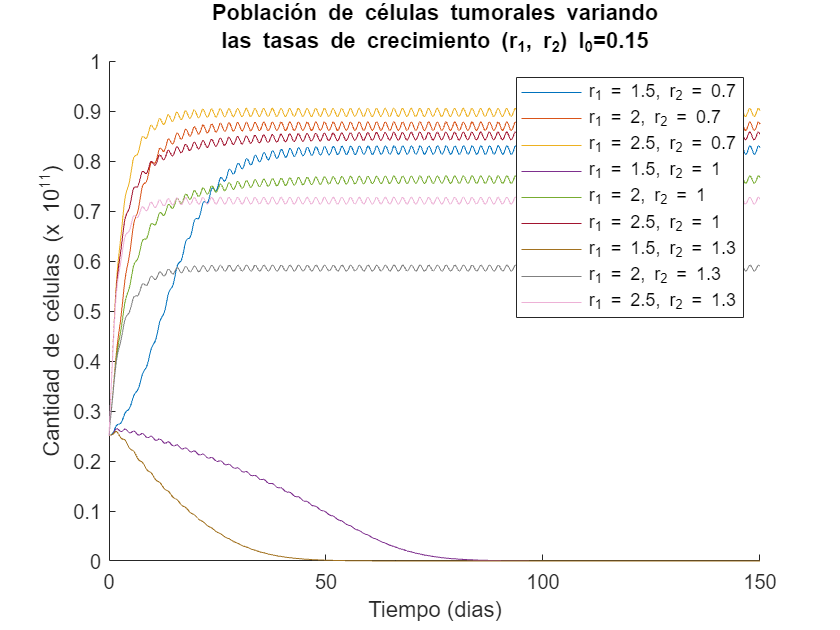

figure; hold on
for i=1:n
    plot(t,Ti(:,i),'Color',colors(i,:))
end
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células tumorales variando", ...
    "las tasas de crecimiento (r_{1}, r_{2}) I_{0}=0.15"])

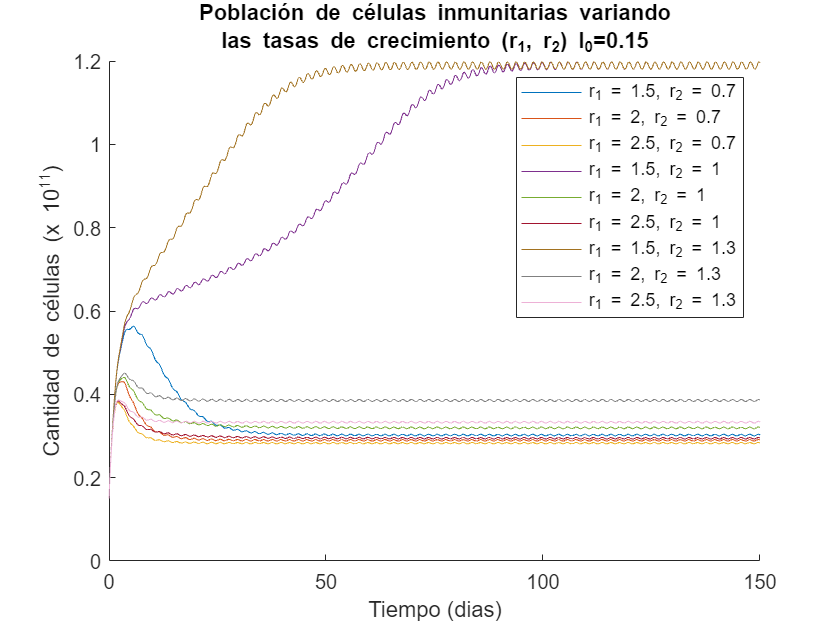

figure; hold on
for i=1:n
    plot(t,Ii(:,i),'Color',colors(i,:))
end
xlabel("Tiempo (dias)")
ylabel("Cantidad de células (x 10^{11})")
legend(leg)
title(["Población de células inmunitarias variando", ...
    "las tasas de crecimiento (r_{1}, r_{2}) I_{0}=0.15"])
hold off


NTab(:,4)=round(min(Ni)',2);
NTab(:,3)=[0 0 0 0.96 0.20 0.11 0.97 0.52 0.42]';

TTab(:,4)=round(max(Ti)',2);
TTab(:,3)=[0.82 0.87 0.70 0 0.76 0.85 0 0.59 0.72]';

ITab(:,4)=round(max(Ii)',2);
ITab(:,3)=[0.30 0.29 0.28 1.19 0.32 0.29 1.19 0.39 0.33]';

plot(t,v(:,2) ,'o')
hold on
plot(t,u)
hold off
xlabel("Tiempo (dias)")
ylabel("Cantidad")
legend(["Dosis de droga" "Droga en el sistema"])
title(["Dosis de droga administrada y", "droga presente en el sistema"])


VarNames=["r1" "r2" "Valor Estable" "Valor Mínimo"];
NTab=array2table(NTab,'VariableNames',VarNames);
NTab = table(NTab,'VariableNames',"Células Normales");
VarNames(end)="Valor Máximo";
TTab=array2table(TTab,'VariableNames',VarNames);
TTab = table(TTab,'VariableNames',"Células Cancerigenas");
ITab=array2table(ITab,'VariableNames',VarNames);
ITab = table(ITab,'VariableNames',"Células Inmunitarias");
disp(NTab)

                 Células Normales              
    r1     r2     Valor Estable    Valor Mínimo
    ___________________________________________

    1.5    0.7           0                0    
      2    0.7           0                0    
    2.5    0.7           0                0    
    1.5      1        0.96              0.7    
      2      1         0.2              0.2    
    2.5      1        0.11             0.11    
    1.5    1.3        0.97             0.79    
      2    1.3        0.52             0.52    
    2.5    1.3        0.42             0.41    



disp(TTab)

               Células Cancerigenas            
    r1     r2     Valor Estable    Valor Máximo
    ___________________________________________

    1.5    0.7        0.82             0.83    
      2    0.7        0.87             0.88    
    2.5    0.7         0.7             0.91    
    1.5      1           0             0.26    
      2      1        0.76             0.77    
    2.5      1        0.85             0.86    
    1.5    1.3           0             0.26    
      2    1.3        0.59             0.59    
    2.5    1.3        0.72             0.73    



disp(ITab)

               Células Inmunitarias            
    r1     r2     Valor Estable    Valor Máximo
    ___________________________________________

    1.5    0.7         0.3             0.56    
      2    0.7        0.29             0.43    
    2.5    0.7        0.28             0.38    
    1.5      1        1.19              1.2    
      2      1        0.32             0.44    
    2.5      1        0.29             0.38    
    1.5    1.3        1.19              1.2    
      2    1.3        0.39             0.45    
    2.5    1.3        0.33             0.39    



## Discusión

En primer lugar, se puede evidenciar que a partir de los puntos de equilibrio y la comparación entre las graficas obtenidas de nuestro modelo y del trabajo de $\textit{De Pillis & Radunskaya (2003)}$, las cuales resultaron equivalentes, de lo que se puede concluir que el modelo desarrollado es correcto para el sistema que se presenta.

Al aplicar la entrada escalón, la cual es una aplicación continua del tratamiento después de cierto tiempo, aunque puede ayudar a eliminar el tumor, disminuye los otros tipos de células por un momento hasta que estas vuelven a comenzar a crecer debido a que la población de células tumorales es menor, lo cual se debe a que estas tienen menos competencia para los recursos, y llegan a un equilibrio. Este equilibrio, aunque sea un equilibrio libre de tumor, las poblaciones de ambas células normales y inmunitarias es menor a como se veía este tipo de equilibrio cuando no se aplica tratamiento, lo cual se debe a que, aunque las células llegaron a un equilibrio en términos de recursos, parte de estas mueren por el tratamiento, que puede llevar a que la cantidad de estas este por debajo de lo que es considerado saludable, es decir, aplicar un tratamiento de forma continua por un largo periodo de tiempo termina siendo contraproducente para la salud del paciente ya que elimina a las células tumorales pero limita el crecimiento de las inmunitarias, lo que concuerda con la primera hipótesis planteada.

A diferencia del escalón, con la entrada del seno y un pulso repetido, el comportamiento de las poblaciones es similar en ambas, ya que el seno resulta ser parecido al pulso porque no tiene sentido aplicar un tratamiento negativo al paciente, por lo que se toma solo cuando es positivo. Al utilizar estas entradas, las células tumorales mueren, y el número de células normales e inmunitarias alcanza un equilibrio en un punto más alto en comparación al obtenido por el escalón, estos resultados son beneficiosos para el paciente ya que la cantidad de células no tumorales resultantes dejan al paciente menos vulnerable a otra enfermedad que pueda contraer.

Al variar la tasa de muerte celular de las células inmunitarias debido al efecto del tratamiento ($a_1$), se puede observar que entre mayor sea la tasa, el tumor toma más tiempo en morir o incluso puede llegar a sobrevivir, debido a que muere una mayor cantidad de células inmunitarias, las cuales tienen el propósito de combatir las células tumorales, por tanto, deja al paciente con menos defensa contra el tumor. Esto implica que, al momento de realizar un tratamiento contra el tumor, se busca disminuir el efecto que este tiene sobre las células inmunitarias.

Cuando los pacientes presentan distintas tasas de respuesta inmunitaria ($\rho
$), el efecto final del tratamiento y las poblaciones de células resultan ser el mismo sin importar el valor de esta tasa, sin embargo, el tiempo que se demora en llegar a este equilibrio aumenta entre menor sea el valor de esta tasa. Esto se puede ver en pacientes que tienen un sistema inmune comprometido, ya que la presencia de alguna amenaza en su organismo tiene un menor estimulo sobre su respuesta inmune. 

Cuando la tasa de respuesta inmune ($\alpha
$) aumenta, el cambio sobre las poblaciones de células no es muy significativo, pero si tiene un pequeño cambio sobre estas. Este aumento en la tasa hace que el número de células inmunitarias disminuya un poco y las células tumorales aumenten debido a que una tasa de umbral inmune alta indica que se requiere un mayor número de células tumorales antes de que el sistema inmunológico responda. Por tanto, una tasa de umbral inmune alta puede indicar una respuesta un poco más débil del sistema inmunológico contra las células tumorales, lo que nos permite concluir que nuestra segunda hipótesis planteada es incorrecta.

Al variar ambas tasas de crecimiento de las células normales y tumorales ($r_2$ y $r_1$ , respectivamente), se puede evidenciar que si la tasa de crecimiento de las normales es baja, mientras que en las tumorales no lo es, la población células normales tiende a morir y entre mayor sea la tasa de crecimiento de las tumorales, más rápido se muere la población, esto se debe al termino de competición entre ambas poblaciones, ya que entre más crezca la población de tumorales más recursos requieren, lo que mata a las normales debido a falta de recursos y como la tasa de crecimiento de estas es baja, mueren más de las que crecen lo que lleva a que la población muera. Cuando la tasa de crecimiento de células normales es más alta, aunque se puede ver que estas sobreviven, hay un efecto sobre la población de las normales al llegar al equilibrio, pues entre mayor sea la diferencia en las tasas de crecimiento esta población en equilibrio es menor ya que como la población de células tumorales llega a un nivel más alto (siempre siendo  $r_2$ < $r_1$) entonces necesitan mayor parte de los recursos, lo que impide que las células normales aumenten debido a la falta de recursos. Las células inmunitarias también se ven afectadas por estas tasas, pues ya que estas también tienen una relación con las tumorales, aunque es de la forma depredador-presa, por tanto, entre mayor sea la población de tumorales en el equilibrio, la población de inmunitarias es menor. Con base en lo mencionado anteriormente, podemos decir que al haber una diferencia significativa entre las tasas de crecimiento $r_1$ y $r_2$ en donde $r_1$ es considerablemente más grande que $r_2$, el tamaño de tumor aumenta significativamente en comparación al número normales incluso llegando al punto en que la población de células normales desaparece, lo que confirma nuestra tercera hipótesis planteada. Además, el caso más favorable para el paciente es cuando la diferencia es pequeña, ya que como el tumor no alcanza a crecer mucho, la población de células normales se puede mantener en un nivel estable y no tener caídas significativas, y el tratamiento puede ser más eficaz en el propósito de eliminar el tumor del organismo, por otra parte al finalizar el tratamiento el organismo del paciente sería menos vulnerable al enfrentarse a futuras enfermedades ya que tendría un nivel más alto de células normales e inmunitarias.

## **Referencias**

De Pillis, Lisette G, & Radunskaya, Ami. 2003. The dynamics of an optimally controlled tumor model: A case study. *Mathematical and computer modelling*, 37(11), 1221–1244.